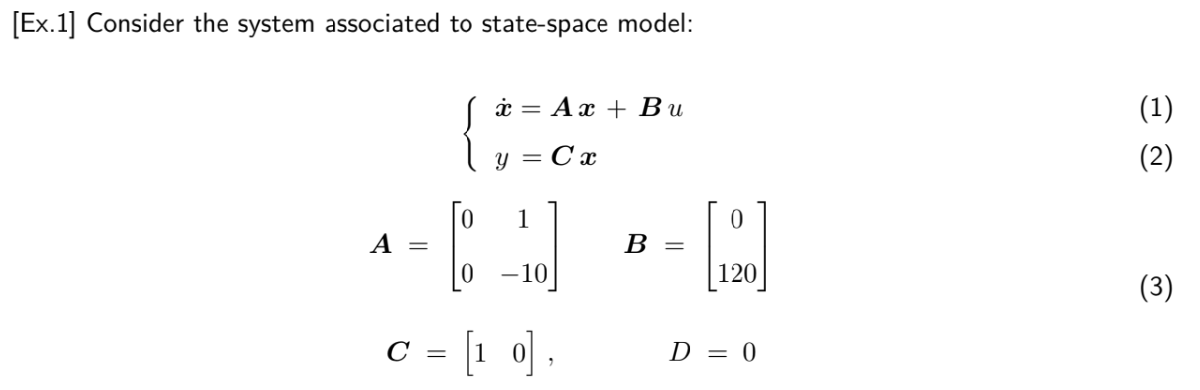

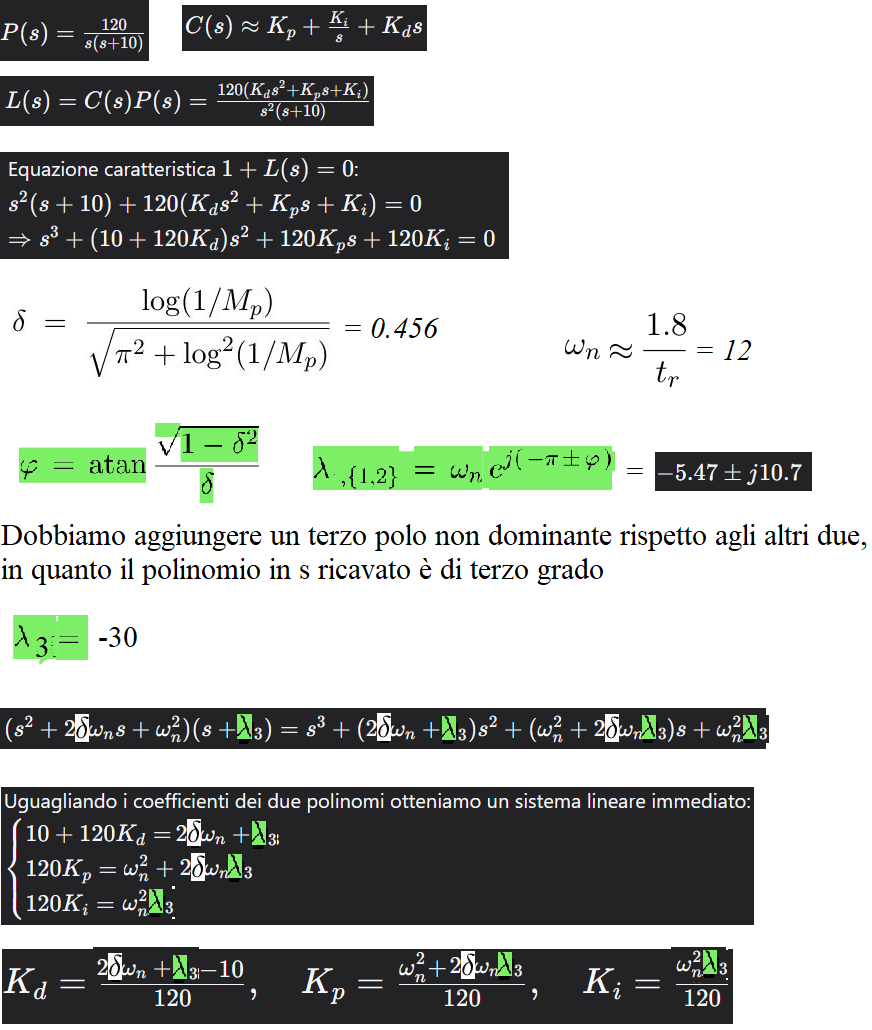

%%Implementazione sistema

clear all;
close all;
clc;

A = [0 1; 0 -10];
B = [0; 120];
C = [1 0];
D = 0;

tr = 0.15; %t rise in secondi

Mp = 0.2; %Sovraelongazione

omega_n = 1.8/tr;

Tl = 1/(8 * omega_n);

sys = ss(A,B,C,D);  % associa le matrici A,B,C,D alle variabili dello state space model
G = tf(sys)  % tf del processo


G =
 
     120
  ----------
  s^2 + 10 s
 
Continuous-time transfer function.
Model Properties


G_bode = zpk(G)  %% Forma fattorizzata di Bode del processo


G_bode =
 
    120
  --------
  s (s+10)
 
Continuous-time zero/pole/gain model.
Model Properties


s = tf('s');
delta = (log(1/Mp))/(sqrt(pi^2+(log(1/Mp))^2));
phi = atan((sqrt(1-delta^2))/(delta));
lambda1 = omega_n*exp(1i*(-pi+phi));
lambda2 = conj(lambda1);
lambda3 = -30;

Kp = (omega_n^2+2*delta*omega_n*(-lambda3))/(120);

Ki = (omega_n^2*(-lambda3))/(120);

Kd = (2*delta*omega_n+(-lambda3)-10)/(120);

C = Kp + Ki/s + Kd*(s/(1+Tl*s));

L = C * G;

T = feedback(L, 1);



info_step = stepinfo(T)

info_step = struct with fields:
         RiseTime: 0.0359
    TransientTime: 0.5111
     SettlingTime: 0.5111
      SettlingMin: 0.9065
      SettlingMax: 1.1961
        Overshoot: 19.6119
       Undershoot: 0
             Peak: 1.1961
         PeakTime: 0.1076
